# Introducción a matemática simbólica

Matlab cuenta con un toolbox de matemática simbólica (ver [[1]](https://www.mathworks.com/products/symbolic.html) y [[2]](https://www.mathworks.com/help/symbolic/)), en este se pueden trabajar funciones simbólicas que representan funciones matemáticas.

Dichas funciones se utilizan para diferenciar, integrar, resolución de ecuaciones diferenciales ordinarias y otras operaciones matemáticas.

## Creación de variables, parámetros y funciones simbólicas

syms a b c      %Definición de variables
b = sym(1/2)    %Definición de parámetros

$$b = \frac{1}{2}$$

syms f(x,y)                 %Definición inicial de funciones simbólicas
                            %junto a sus variables independientes

f(x,y) = x^2 + 7*x*y + y^2  %Especificación de la expresión matemática

$$f(x, y) = x^{2}+7\,x\,y+y^{2}$$

## Evaluación de funciones simbólicas

x1 = 0:5;           %Vectores de valores de variable independiente x1=[0,1,2,3,4,5]
y1 = 1:2:11;        %Vectores de valores de variable independiente y1 = [1,3,5,7,9,11]
f(x1, y1)           %Evaluar los valores de las variables independientes

$$ans = \left(\begin{array}{cccccc} 1 & 31 & 99 & 205 & 349 & 531 \end{array}\right)$$

## Funciones básicas para el curso

### **solve** 

Solución simbólica de ecuaciones algebraicas

syms x
ecu = x^2 + 3*x +2 == 0

$$ecu = x^{2}+3\,x+2=0$$

sol = solve(ecu)

$$sol = \left(\begin{array}{c} -2\\ -1 \end{array}\right)$$

### **subs**

Substituye variables en expresiones simbólicas

syms x k
eqn = sin(2*x) + cos(x) == 0

$$eqn = \sin\left(2\,x\right)+\cos\left(x\right)=0$$

[solx, params, conds] = solve(eqn, x, 'ReturnConditions', true)

$$solx = \left(\begin{array}{c} \frac{\pi }{2}+\pi \,k\\ 2\,\pi \,k-\frac{\pi }{6}\\ \frac{7\,\pi }{6}+2\,\pi \,k \end{array}\right)$$

$$params = k$$

$$conds = \left(\begin{array}{c} k\in \mathbb{Z}\\ k\in \mathbb{Z}\\ k\in \mathbb{Z} \end{array}\right)$$

subs(solx, k, 10)

$$ans = \left(\begin{array}{c} \frac{21\,\pi }{2}\\ \frac{119\,\pi }{6}\\ \frac{127\,\pi }{6} \end{array}\right)$$

### vpasolve

Solución numérica de ecuaciones algebraicas

syms x
ecu = x^3 + 3*x +2 == 0;
sol = vpasolve(ecu,x)

$$sol = \left(\begin{array}{c} -0.59607163798332152311280541439968\\ 0.29803581899166076155640270719984+1.8073394944520218535764598429639\,\mathrm{i}\\ 0.29803581899166076155640270719984-1.8073394944520218535764598429639\,\mathrm{i} \end{array}\right)$$

### inv

Inversa de una matriz cuadrada

syms a b c d
M = [a b; c d];
inv(M)

$$ans = \left(\begin{array}{cc} \frac{d}{a\,d-b\,c} & -\frac{b}{a\,d-b\,c}\\ -\frac{c}{a\,d-b\,c} & \frac{a}{a\,d-b\,c} \end{array}\right)$$

### simplify

Simplificación algebraica

syms x a b c
Identity = sin(x)^2 + cos(x)^2

$$Identity = {\cos\left(x\right)}^{2}+{\sin\left(x\right)}^{2}$$

S = simplify(Identity)

$$S = 1$$

### expand

Expande expresiones y simplifica las entradas de funciones mediante el uso de identidades

syms x
p = (x - 2)*(x - 4)

$$p = \left(x-2\right)\,\left(x-4\right)$$

expand(p) 

$$ans = x^{2}-6\,x+8$$

### symunit

Agrega unidades de medida a las variables y parámetros simbólicos

u = symunit;
length = 3*u.m       %unidades de distancia (metros)

$$length = 3\,m$$

g = 9.81*u.m/u.s^2   %unidades para aceleración (metros/segundo^2)

$$g = \frac{981}{100}\,\frac{m}{s^{2}}$$

### unitConvert

Sirve para hacer conversiones de unidades

m = 2*u.kg;             %masa
a = 5*u.m/u.s^2;        %aceleración
F = m*a                 %Fuerza

$$F = 10\,\frac{\mathrm{kg}\,m}{s^{2}}$$

F = unitConvert(F,u.N)  %unidades en Newton

$$F = 10\,N$$

### rewrite

Reescribir una expresión en términos de otra función

syms x
rewrite(cos(x),'sin')

$$ans = 1-2\,{\sin\left(\frac{x}{2}\right)}^{2}$$

### coeffs

Coeficientes de un polinomio

syms x
Poly = 16*x^2 + 19*x + 11;
c = coeffs(Poly)

$$c = \left(\begin{array}{ccc} 11 & 19 & 16 \end{array}\right)$$

### fplot

Se logran graficar expresiones o funciones simbólicas

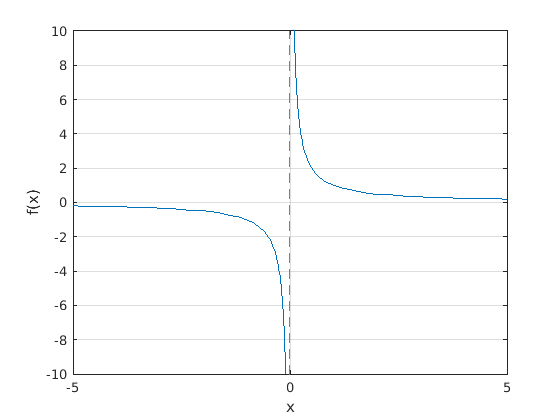

syms x
f = 1/x;
fplot(f)
xlabel('x')
ylabel('f(x)')
grid on

### limit

Calcula el límite de una función

syms x
f = 1/x;
limit(f,x,0)            %límite bidireccional

$$ans = \mathrm{NaN}$$

limit(f,x,0,'right')    %límite por la derecha

$$ans = \infty$$

limit(f,x,0,'left')     %límite por la izquierda

$$ans = -\infty$$

### diff

Diferencia una expresión o función simbólica

syms x
f = x^3

$$f = x^{3}$$

diff(f)

$$ans = 3\,x^{2}$$

### int

Realiza integrales definidas e indefinidas

syms x

expr = 1+x^2;
F = int(x)      %Integral indefinida de una función univariada

$$F = \frac{x^{2}}{2}$$

syms x z
f(x,z) = x/(1+z^2);
Fx = int(f,x)   %Integral indefinida de una función multivariada en terminos de x

$$Fx(x, z) = \frac{x^{2}}{2\,\left(z^{2}+1\right)}$$

syms x
expr = 1-exp(-x);
F = int(expr,[0 1])   %Integral definida entre 0 y 1

$$F = {\mathrm{e}}^{-1}$$

### taylor

Obtiene series de taylor de una expresión

syms x
f = exp(x);
T1 = taylor(f)

$$T1 = \frac{x^{5}}{120}+\frac{x^{4}}{24}+\frac{x^{3}}{6}+\frac{x^{2}}{2}+x+1$$

## **Otros ejemplos**

Ecuaciones algebraicas y poliomios

syms x; ecu = x^2 + 3*x +2 == 0, sol = solve(ecu,x)

$$ecu = x^{2}+3\,x+2=0$$

$$sol = \left(\begin{array}{c} -2\\ -1 \end{array}\right)$$

syms x; y = x^2 + 3*x +2 == 0, sol = solve(y)

$$y = x^{2}+3\,x+2=0$$

$$sol = \left(\begin{array}{c} -2\\ -1 \end{array}\right)$$

syms x; ecu = x^7 + 3*x +2 == 0, sol = vpasolve(ecu,x)

$$ecu = x^{7}+3\,x+2=0$$

$$sol = \left(\begin{array}{c} -0.65027708408882095477083343054081\\ -0.90036791588067295118938690146048+0.64788188572106682921275303768577\,\mathrm{i}\\ -0.90036791588067295118938690146048-0.64788188572106682921275303768577\,\mathrm{i}\\ 0.097925603743129568327877127978678-1.2295605264916299924750226730771\,\mathrm{i}\\ 0.097925603743129568327877127978678+1.2295605264916299924750226730771\,\mathrm{i}\\ 1.1275808541819538602469264887522+0.60954942984727465814814446860187\,\mathrm{i}\\ 1.1275808541819538602469264887522-0.60954942984727465814814446860187\,\mathrm{i} \end{array}\right)$$

syms x; ecu = x-10*sin(x) == 0, sol = vpasolve(ecu,x)

$$ecu = x-10\,\sin\left(x\right)=0$$

$$sol = 0$$

syms x; ecu = x-10*sin(x) == 0, sol = vpasolve(ecu,x,2)

$$ecu = x-10\,\sin\left(x\right)=0$$

$$sol = 2.8523418944500916483252199407028$$

syms x; f = 16*x^2 + 19*x + 11, c = coeffs(f)

$$f = 16\,x^{2}+19\,x+11$$

$$c = \left(\begin{array}{ccc} 11 & 19 & 16 \end{array}\right)$$

syms x; p = (x - 2)^2*(x - 4), expand(p)

$$p = {\left(x-2\right)}^{2}\,\left(x-4\right)$$

$$ans = x^{3}-8\,x^{2}+20\,x-16$$

syms x y; f = cos(x + y), expand(f)

$$f = \cos\left(x+y\right)$$

$$ans = \cos\left(x\right)\,\cos\left(y\right)-\sin\left(x\right)\,\sin\left(y\right)$$

syms x; p = x^4 - 1.5, F = factor(p)

$$p = x^{4}-\frac{3}{2}$$

$$F = \left(\begin{array}{cc} \frac{1}{2} & 2\,x^{4}-3 \end{array}\right)$$

syms x; p = x^4 - 1.5, F = factor(p,'FactorMode', 'complex')

$$p = x^{4}-\frac{3}{2}$$

$$F = \left(\begin{array}{cccc} x+1.1066819197003215924087902734403 & x-1.1066819197003215924087902734403 & x+1.1066819197003215924087902734403\,\mathrm{i} & x-1.1066819197003215924087902734403\,\mathrm{i} \end{array}\right)$$

syms s; f = 1/((s-1)*(s+1)^2*(s^2+4)), F = partfrac(f)

$$f = \frac{1}{\left(s^{2}+4\right)\,\left(s-1\right)\,{\left(s+1\right)}^{2}}$$

$$F = \frac{\frac{s}{25}-\frac{1}{25}}{s^{2}+4}+\frac{1}{20\,\left(s-1\right)}-\frac{9}{100\,\left(s+1\right)}-\frac{1}{10\,{\left(s+1\right)}^{2}}$$

### Simplificación de ecuaciones

syms x; z = sin(x)^2 + cos(x)^2, simplify(z)

$$z = {\cos\left(x\right)}^{2}+{\sin\left(x\right)}^{2}$$

$$ans = 1$$

syms x; z = (x^2 - 4)/(x+2), simplify(z)

$$z = \frac{x^{2}-4}{x+2}$$

$$ans = x-2$$

syms x; z = log(exp(-3*x)), simplify(z,'IgnoreAnalyticConstraints',true)

$$z = \log\left({\mathrm{e}}^{-3\,x}\right)$$

$$ans = -3\,x$$

syms a b; z = cos(a) + sin(b), subs(f, [a,b], [sym('alpha'),2])

$$z = \cos\left(a\right)+\sin\left(b\right)$$

$$ans = \frac{1}{\left(s^{2}+4\right)\,\left(s-1\right)\,{\left(s+1\right)}^{2}}$$

### Unidades

u = symunit; z = 3.2*u.cm + 4.5*u.m, simplify(z),rewrite(z,u.m)

$$z = \frac{16}{5}\,\mathrm{cm}+\frac{9}{2}\,m$$

$$ans = \frac{2266}{5}\,\mathrm{cm}$$

$$ans = \frac{1133}{250}\,m$$

u = symunit; z = 3.2*u.cm + 4.5*u.m, unitConvert(z,u.m)

$$z = \frac{16}{5}\,\mathrm{cm}+\frac{9}{2}\,m$$

$$ans = \frac{1133}{250}\,m$$

### Solución de un sistemas de ecuaciones

syms x y z; ec1 = 2*x + 3*y - 4*z == 1; ec2 = x - y +3.4*z == -2.3; ec3 = x - 7.4*z == 0; ecu = [ec1; ec2; ec3], sol = solve(ecu); sol.x, sol.y, sol.z

$$ecu = \left(\begin{array}{c} 2\,x+3\,y-4\,z=1\\ x-y+\frac{17\,z}{5}=-\frac{23}{10}\\ x-\frac{37\,z}{5}=0 \end{array}\right)$$

$$ans = -\frac{2183}{2160}$$

$$ans = \frac{33}{40}$$

$$ans = -\frac{59}{432}$$

syms x y z a b; ec1 = a*x + 3*y - b*z == 1; ec2 = x - y +b*z == -2.3; ec3 = x - a*z == 0; ecu = [ec1; ec2 ;ec3], sol = solve(ecu); sol.x, sol.y, sol.z

$$ecu = \left(\begin{array}{c} 3\,y+a\,x-b\,z=1\\ x-y+b\,z=-\frac{23}{10}\\ x-a\,z=0 \end{array}\right)$$

$$ans = -\frac{59\,a}{10\,\left(a^{2}+3\,a+2\,b\right)}$$

$$ans = \frac{23\,a^{2}+10\,a-13\,b}{10\,\left(a^{2}+3\,a+2\,b\right)}$$

$$ans = -\frac{59}{10\,\left(a^{2}+3\,a+2\,b\right)}$$

subs(sol.x,a,1)

$$ans = -\frac{59}{10\,\left(2\,b+4\right)}$$

### Matrices

syms a; A = [1 2 a; 2 -2 1; 2 -4 a], inv(A)

$$A = \left(\begin{array}{ccc} 1 & 2 & a\\ 2 & -2 & 1\\ 2 & -4 & a \end{array}\right)$$

$$ans = \begin{array}{l} \left(\begin{array}{ccc} \frac{a-2}{5\,a-4} & \frac{3\,a}{5\,a-4} & -\frac{a+1}{5\,a-4}\\ \frac{a-1}{5\,a-4} & \frac{a}{\sigma_{1}} & -\frac{2\,a-1}{\sigma_{1}}\\ \frac{2}{5\,a-4} & -\frac{4}{5\,a-4} & \frac{3}{5\,a-4} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=2\,\left(5\,a-4\right) \end{array}$$

syms a; A = [1 2 a; 2 -2 1; 2 -4 a], det(A)

$$A = \left(\begin{array}{ccc} 1 & 2 & a\\ 2 & -2 & 1\\ 2 & -4 & a \end{array}\right)$$

$$ans = 8-10\,a$$

syms x y z a b; A = [a*x 3*y -b*z -1; x -y b*z 2.3; x 0 -a*z 0], sol = rref(A)

$$A = \left(\begin{array}{cccc} a\,x & 3\,y & -b\,z & -1\\ x & -y & b\,z & \frac{23}{10}\\ x & 0 & -a\,z & 0 \end{array}\right)$$

$$sol = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{59\,a}{10\,x\,\left(a^{2}+3\,a+2\,b\right)}\\ 0 & 1 & 0 & -\frac{23\,a^{2}+10\,a-13\,b}{10\,y\,\left(a^{2}+3\,a+2\,b\right)}\\ 0 & 0 & 1 & \frac{59}{10\,\left(z\,a^{2}+3\,z\,a+2\,b\,z\right)} \end{array}\right)$$

### Cáculo

syms x h; f = sin(x)/(x+h), limit(f,x,0,'left')

$$f = \frac{\sin\left(x\right)}{h+x}$$

$$ans = \left\{ \begin{array}{cl} 1 & \text{ if }h=0\\ 0 & \text{ if }h\neq 0 \end{array}\right.$$

syms f x y; f = x*y*cos(x)*sin(y^2), Dfx = diff(f,x), Dfy = diff(f,y), Dfx3 = diff(f,x,3), Dfx2y2 = diff(f,x,x,y,y)

$$f = x\,y\,\sin\left(y^{2}\right)\,\cos\left(x\right)$$

$$Dfx = y\,\sin\left(y^{2}\right)\,\cos\left(x\right)-x\,y\,\sin\left(y^{2}\right)\,\sin\left(x\right)$$

$$Dfy = x\,\sin\left(y^{2}\right)\,\cos\left(x\right)+2\,x\,y^{2}\,\cos\left(y^{2}\right)\,\cos\left(x\right)$$

$$Dfx3 = x\,y\,\sin\left(y^{2}\right)\,\sin\left(x\right)-3\,y\,\sin\left(y^{2}\right)\,\cos\left(x\right)$$

$$Dfx2y2 = 8\,y^{3}\,\sin\left(y^{2}\right)\,\sin\left(x\right)-12\,y\,\cos\left(y^{2}\right)\,\sin\left(x\right)-6\,x\,y\,\cos\left(y^{2}\right)\,\cos\left(x\right)+4\,x\,y^{3}\,\sin\left(y^{2}\right)\,\cos\left(x\right)$$

syms x; y = sin(x), y2 = taylor(y,'ExpansionPoint',0)

$$y = \sin\left(x\right)$$

$$y2 = \frac{x^{5}}{120}-\frac{x^{3}}{6}+x$$

syms x; y = -2*x/(1+x^2)^2, int(y)

$$y = -\frac{2\,x}{{\left(x^{2}+1\right)}^{2}}$$

$$ans = \frac{1}{x^{2}+1}$$

syms x; y = -2*x/(1+x^2)^2, int(y,[0,inf])

$$y = -\frac{2\,x}{{\left(x^{2}+1\right)}^{2}}$$

$$ans = -1$$

$$y1 = \tan\left(x\right)$$

$$y2 = \log\left(x\right)$$

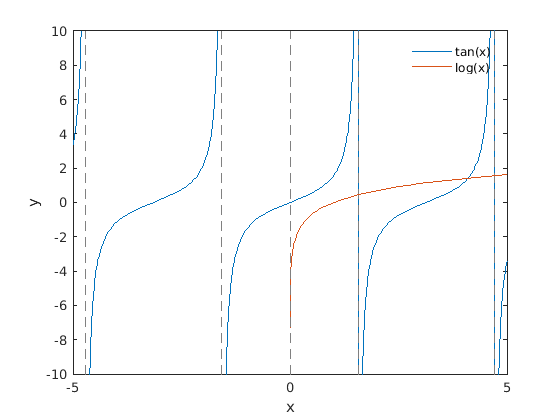

syms x; y1 = tan(x), y2 = log(x), fplot([y1,y2],[-5,5]),legend("tan(x)","log(x)","box","off"), xlabel('x'), ylabel('y')